# Demonstration Script 

## Elastic Moduli Fitting using Function Velocities2Cij

The following sections of text and code illustrate the use of Velocities2Cij as described in *Determination of Elastic Moduli from Measured Acoustic Velocities*.  Necessary data files are included with the Supplemental Materials. MATLAB version 2016a or later is required to execute this "live" script. Run sections of this script sequentially by clicking to highlite a single script section and then clicking on the bar on the left (or clicking "Run Sections" in the top menu bar. Embedded green text provides additional comments about each command line statement. This script is set to show results in line rather than in a separate column.

## Articulation of the Standard Workflow

The stardard work flow requires finding a set of moduli and euler angles that provide calculated velocities in accord with data (i.e. chisqr is reasonably close to 1). The methods discussed below are sequentially applied through execution of a command line function.

If different initial guesses and different fitting algorithms fail to find a solution with an acceptable chisqr, several alternatives need to be explored.  (1) Have transverse velocity data been assigned to the correct polarization (an examination of the velocity misfit plot can aid in this analysis)? (2) Is there a mistake in the euler angles (this is futher discussed below)?  (3) Are experimental uncertainties larger than those estimated?

**Units**

Elastic moduli are in units of GPa Elastic compliances are in units of TPa^-1.  Density is in units of kg/m^3.  Angles are given in degress.

**Vector Representation of Tensor Elements**

Moduli are listed in cyclic order: C11 C12 ... C21 C22  C23 ... 

**Surface Wave Fitting**

A FORTRAN program (Every AG, Kim KY, Maznev AA (1998) Surface dynamic response functions of anisotropic solids. Ultrasonics 36:349–353) is used in fitting surface wave velocities.  The program has been modified to find the maxima of surface wave amplitudes at the velocities associated with Rayleigh waves or psuedo surface waves and is implemented within MATLAB as  a "mex" function. This provides a forward calculation that is then used in the fitting process.  Since these calculations are numerically intensive, parallelization has also been implemented through use of Open MP commands. The included executable code (.mexmaci64)  runs on the macOS (10.13.3) using MATLAB versions 2016a and later. The Open MP commands were not successfuly compiled and linked in the current release (but worked well in earlier versions of MATLAB and macOS).  The user will need to compile and link the FORTRAN if using other operating systems or if an effort is made to gain speed through parallel execution.

# Fitting Bodywave Data from Collins and Brown (1998) for a monoclinic pyroxene mineral

## Load and Examine Data and Data Structure:

This example, based on data from Collins and Brown (1998), follows discussion in the "Workflow Example" section of the paper and results are summarized in Table 1 of the paper.   Data to be analyzed are contained in the function mkStrCPX which returns initial values for moduli and euler angels and a structure that contains all measure velocities and other data necessary for fitting. This file can be examined in an edit window.  The organization of this file can serve as a template for creating new data files. In this example, an input string of 'p' for mkStrCPX returns the published elastic moduli in variable "Co" and the euler angles for the individual samples of the data set in variable "ea".  Any input string other than 'p' causes the function to return silicate default moduli  (C11=C22=C33 =100 , C12=C13=C23=50, C44=C55=C66=50, all other Cij = 0) . 

[Input,Co,ea]=mkStrCPX('p');

Typing the output variable names shows what they contain: 

Co % the initial guess moduli - always in cyclic order C11 C12 C13 ... C22 C23 ... C33  ... C44 ...

Co =         237.8         83.5           80            9        183.6         59.9          9.5        229.5           48         76.6          8.4           73         81.6



ea % the measured euler angles vertical columns for each sample ( three samples in this case)

ea =           7.9          269        345.2
         89.6         85.4          7.3
          3.2        193.4        345.5



Input % the structure is divided into two sections (1) "Data" contains experiment information and 

Input = struct with fields:
    Data: [1×1 struct]
    opts: [1×1 struct]


      %      (2) "opts" contains fitting options or quantities  that change as a result of fitting:                                                
display(Input.Data)  % show what is in the Data part of the structure

           name: 'Collins and Brown CPX 1998'
        dcosflg: 0
          nsamp: 3
            sym: 'm'
            rho: 3.327
         Cguess: [237.8 83.5 80 9 183.6 59.9 9.5 229.5 48 76.6 8.4 73 81.6]
          Trust: [1×1 struct]
    eulerangles: [3×3 double]
         sample: [1×3 struct]



Since for this data set, propagation directions are calculated from the euler angles rather than being directly specified by direction cosines,  the variable "dcosflg" is set to 0.  

The opts side of the structure contains "working" values of moduli and euler angles - these are modified during fitting. "ifit" provides indexes for samples to be fit (i.e. ifit=1 would allow only velocities and euler angles for the first sample to be used in fitting.) "iconst" gives the indexes of moduli to optimize (i.e. iconst=[1 6 13] would leave all constants other than these constant and just optimize these 3).

display(Input.opts) % show what is in the options part of the structure

      constants: [237.8 83.5 80 9 183.6 59.9 9.5 229.5 48 76.6 8.4 73 81.6]
           ifit: [1 2 3]
         iconst: [1 2 3 4 5 6 7 8 9 10 11 12 13]
    eulerangles: [3×3 double]



## Run Velocities2Cij using Previously Reported Moduli

The function Velocities2Cij is called below with fitting flags set to "no" ('n').  This gives the statistics associated with the initial moduli and euler angles.  'Cout'  and 'eaout' in this case are returned as the initial input 'Co' and 'ea' values. The structure 'Results' contains all relevant calculational results.

[Cout,eaout,Results]=Velocities2Cij(Input,Co,'n',ea,'n','LM');  % just calculate results for input moduli

rms misfit =20.8 m/s  chisqr =   1.01  elapsed time  0.0 s 



The command line output shows the root-mean-square misfit, the chisqr misfit, and the time required for the calculations.  Since the moduli and euler angles are those from the original paper, the command line output shows the same goodness of fit metrics as given in the paper.  The chisqr metric near one indicates that the estimations of experimental errors in velocity determinations are consistent with misfits of velocities using the given moduli.

## Examine Results

For this first example, the quantities in the 'Results' structure are shown below.  Note that this output structure contains nested structures and both numerical and string arrays.

Results

Results = struct with fields:
     datestamp: '06-Feb-2018 17:48:37'
    InputStrct: [1×1 struct]
        CijSij: [13×4 double]
     BWResults: [1×1 struct]
           rms: 20.847
         chisq: 1.0148
            KG: [122 0.6 112.4 0.8 74.7 0.3 69.9 0.2]
          comp: [1.91 3.63 3.35 0 -2.91 0]
        Method: 'LM'
     RefineCij: 'n'
      Refineea: 'n'


Note that the input structure has been appended to the "Results" structure to preserve a record of exactly what information was used in the calculations.  The "KG" data array gives Voigt and Ruess estimates of the isotropic bulk and shear moduli with the associated uncertainties. The "comp" data are elements of the axes compressibility tensor.  These are important in the case of surface wave fitting where an independent constraint is needed to reduce covariance for some moduli (see Brown et al 2006 "Triclinic Elastic Constant for Low Albite").  User selected fitting methods include "LM" (Levenberg Marquardt), "NM' (Nelder Mead), or "BG" (Backus Gilbert). The matrix of results "CijSij" gives (column 1) moduli GPa units) , (column 2) 2 sigma uncertainties , (column 3) Compliances (TPa^-1 units) and (column 4) their 2 sigma uncertainties

disp(Results.CijSij)

        237.8          1.3         5.38         0.04
         83.5          1.4           -2         0.05
           80          1.3        -1.47         0.04
            9          0.8         0.56         0.06
        183.6          1.2          6.7         0.05
         59.9          1.6        -1.07         0.07
          9.5            1         0.08         0.11
        229.5          1.1         5.89         0.04
           48          0.7        -3.55         0.05
         76.6            1         13.2         0.17
          8.4          0.8        -1.36         0.13
           73          0.4        15.96         0.08
         81.6          1.2        12.39         0.19



A comparison of predicted velocities and data can be plotted (shown below) if data are reported in distinct planes of rotation. The number of the plot window in this example is set to 99. The plotting range for deviations is set to 2% as the last input variable to the plotting function. Note that transverse waves are organized by their relative velocity and not by polarization (triangles for faster transverse velocities and asterisks for the slower branch).  When both waves are observed, this distinction is straightforward. However, in many cases only one transverse velocity is measured and judgement or experimentation is required to correctly assign data to the branch.

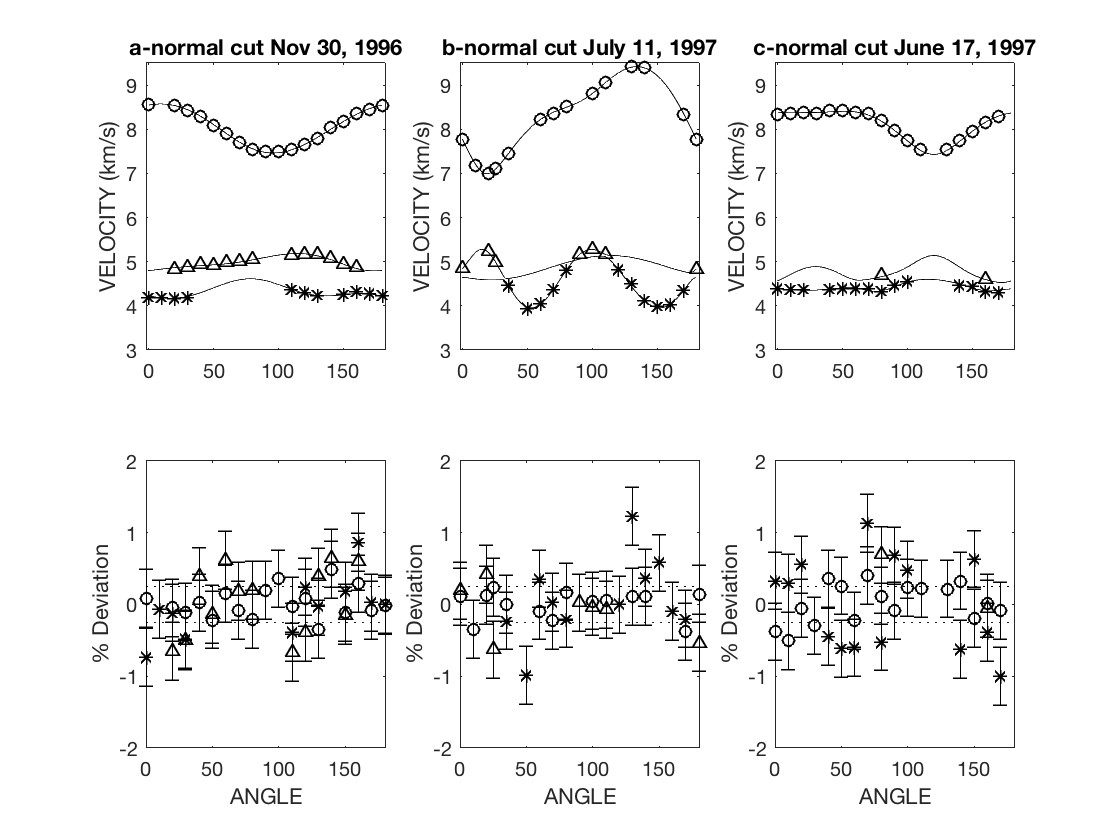

BWPlot(Results,99,2)

## Run Velocities2Cij from a Non-Optimal Initial Set of Moduli using the Levenberg Marquardt Algorithm 

The function Velocities2cij can generate random starting moduli (within a range specified in the input structure as the "trust region").  Here the data are fit starting from a random set of moduli - using the 'r' flag below. If chisqr is larger than 1, trying running again from a different random starting point. In most cases the fitter will find an adequate fit.  In some cases it might find a local minimum with unacceptable misfit.  Fitting algorithm is set in the function call: Levenberg-Marquardt fitter is invoked using  'LM' in the input list,  Backus Gilbert fitter is invoked using 'BG'  and Nelder Mead is invoked using "NM".

[Cf,eaout,Results,Ct]=Velocities2Cij(Input,Cout,'r',ea,'n','LM',1);

iteration    chisqr      optimality       lambda      relaxation
   0       1377.763      7.248e+02       1.000e-02     1.000e+00
   1        122.696      1.023e+01       1.000e-03     1.250e+00
   2          7.017      1.649e+01       1.000e-04     1.562e+00
   3          2.839      1.472e+00       1.000e-05     1.953e+00
   4          2.613      8.658e-02       1.000e-06     2.441e+00
  10          2.613      3.828e+05       1.000e-02     1.000e+00
  11          0.992      1.634e+00       1.000e-03     1.250e+00
  12          0.990      1.629e-03       1.000e-04     1.562e+00
  13          0.990      6.152e-05       1.000e-05     1.953e+00
  18          0.990      1.010e+06       1.000e-02     1.000e+00
  19          0.990      2.651e-05       1.000e-03     1.250e+00
rms misfit =20.6 m/s  chisqr =   0.99  elapsed time  0.2 s 



Note that the optional ouput variable 'Ct' contains the input moduli which in this case were randomly generated (the 'r' in the list of input variables). 

## Run Velocities2Cij from a Non-Optimal Initial Set of Moduli using the Backus Gilbert Algorithm

Instead of using the Levenberg-Marquardt fitter, the Backus Gilbert fitter is invoked using 'BG'  and using the same input moduli as  in the previous fitting:

[Cf,eaout,Results,Ct]=Velocities2Cij(Input,Ct,'y',ea,'n','BG',1);

iteration    chisqr      optimality      variance     relaxation
   0       1377.763      7.248e+02       7.302e-01     3.000e-01  
   1        632.696      1.178e+00       3.566e-01     3.750e-01  
   2        286.216      1.211e+00       1.690e-01     4.688e-01  
   3        141.581      1.022e+00       7.951e-02     5.859e-01  
   4         71.903      9.691e-01       3.752e-02     7.324e-01  
   5         36.597      9.647e-01       1.744e-02     9.155e-01  
   6         11.411      2.207e+00       5.299e-03     1.144e+00  
   7          2.776      3.111e+00       1.206e-03     1.431e+00  
   8          1.196      1.321e+00       5.001e-04     1.788e+00  
   9          1.170      2.233e-02       4.826e-04     2.235e+00  
  20          1.170      8.548e+05       4.826e-04     3.000e-01  
  21          1.075      8.866e-02       4.513e-04     3.750e-01  
  22          1.024      4.916e-02       4.344e-04     4.688e-01  
  23          1.004      2.024e-02       4.274e-04     5.859e-01

Note here that that rms misfit is minimized rather than the chi^2 (per Weidner and Carlton 1978).  If this fitter stalls at chisqr>1, try another starting point for moduli - by hand editing Ct,  creating another Ct in the previous section of this script, or changing the fitting flag from 'y' to 'r'.

## Run Velocities2Cij from a Non-Optimal Initial Set of Moduli using the Nelder Mead Algorithm

Another algorithm is the Nelder-Mead simplex.  This is invoked with the 'NM' flag. 

[Cf,eaout,Results,Ct]=Velocities2Cij(Input,Ct,'y',ea,'n','NM',1);

iteration    chisqr  
   0         1377.76   
 700           24.49   
1400            1.63   
2100            0.99   
2556            0.99   
rms misfit =20.6 m/s  chisqr =   0.99  elapsed time  2.7 s 



## Multistart  Fitting

Any non-linear parameter optimization algorithm can stall in a local minimum with a misfit larger than expected (chisqr >>1).  One can restart the simplex from the previous best fit

               [Cf,eaout,Results,Ct]=Velocities2Cij(Input,Cf,'y',ea,'n','NM',1);

As long as the moduli going into the fit have changed from those previously returned, the simplex method will undertake a search that is different from the previous.

Or simply try starting again from a different random set of moduli

[Cf,eaout,Results]=Velocities2Cij(Input,Cf,'r',ea,'n','NM',1);

iteration    chisqr  
   0          540.06   
 700           36.74   
1400            3.60   
2100            3.47   
2640            3.47   
rms misfit =40.5 m/s  chisqr =   3.47  elapsed time  2.7 s 



The speed of the simplex algorithm, while significantly slower than the gradient-based algorithms, is still adequately fast and in some cases can find a better solution than the gradient-based methods.  Repeat this section several times by clicking on the bar to the left..  If the fitter stalls at an unacceptable chisqr, try restarting the fitter after changing the fitting flag to 'y'. If the simplex method wanders into an unphysical state (on-positive-definite moduli), just try again from a different initial guess.

## Determining Euler Angles

The ability to optimize Euler angles is often necessary since wave propagation directions may have non-negligible uncertainties associated with the mechanical steps separating an x-ray alignment of a crystal with its placement in an experiment. As noted by Every (1980), the three angles necessary to describe an orientation in laboratory coordinates are simply additional parameters to optimize. Here a test is performed to explore the ability of velocity data sets to constrain the Euler angles. Below, the orientations of Euler angles are intentionally randomized with a variance of 4 degrees. The exercise can be repeated from different sets of randimized euler angles with each click on the bar to the left

The initial euler angles are shown as:

disp(ea)

          7.9          269        345.2
         89.6         85.4          7.3
          3.2        193.4        345.5



Euler angles are perturbed with a variance of 4°:

ear=ea+4*randn(3,3);disp(round(10*ear)/10)

          9.9        274.7        351.6
         88.9         86.6          4.1
          2.4        194.2        348.3



These Euler angles with synthetic “experimental error” are then optimized against the velocity data by invoking the following command:

[Cf,eaout,Results,Ct]=Velocities2Cij(Input,Cout,'n',ear,'y','LM',1);

rms misfit =20.9 m/s  chisqr =   1.02  elapsed time  0.1 s 



The recovered Euler angles typically agree with the original values to a few tenths of a degree or better. 

display(round(10*(ea-eaout))/10)

            0         -0.3          0.2
            0            0            0
            0            0          0.1



When both optimized moduli and Euler angles are required, experience has shown that even with completely unknown Euler angles, a process of alternation between fitting for moduli and fitting for Euler angles converges to the correct results. 

# Demonstration of Velocities2Cij for Several Additional Examples

Data sets included with the supplemental materials are analyzed.  These examples illustrate several additional features of the software and allow comparisons with previously published results.  Results of the calculations shown below are reported in Tables 1 through 5 of the paper.

## Example 2: Fitting the Weidner and Carlton Coesite data: loading and validating data and fit

**Coesite: **(function providing data: `mkStrCoesite)` The pioneering data set of Weidner and Carleton (1977) is revisited with this example. Coesite is monoclinic and thus requires 13 elastic moduli. Measurements were reported in 96 directions. Not all polarizations of body waves were observed in any one direction. Six of the data deviated so strongly that even though listed in the table these points were excluded from the originally published fit.  The reported *rms* misfit of 151 m/s is approximately an order of magnitude larger than is typically achieved in current generation experiments. 

Direction cosines and observed velocities were copied directly from the paper into the example file `mkStrCoesite.m`. Experimental uncertainties (180 m/s for transverse waves and 130 m/s for compressional waves) were assigned based on the average misfits reported in the paper. Examination of the data indicates that most of the direction cosines lie on several planes.  Thus, a set of Euler angles could, in principle, be used to describe the propagation directions. However, here only the reported direction cosines are used in the optimization. In the function call `mkStrCoesite(Cflg)`, setting `Cflg` to `‘p’ `returns the published moduli in the variable `Co`. Any other string or no input arguments returns a default silicate set of moduli.  The commands below demonstrate loading the data, checking that the published results are duplicated, and then attempting further optimize using both Levenberg-Marqardt and Backus Gilbert methods. The moduli uncertainties on the basis of a Monte Carlo test are also evaluated. Results are summarized in Table 2 of the paper.

[Input,Cout,ea]=mkStrCoesite('p');
[Cf,eaout,Results]=Velocities2Cij(Input,Cout,'n',ea,'n','LM',1);

rms misfit =151.6 m/s  chisqr =   1.01  elapsed time  0.0 s 



The first line loads the data.  The second line with fitting flags set to ‘n’ calculates results based on the input moduli.  The misfit of 152 m/s is in agreement with the original publication. 

## Example 2: Fitting the Weidner and Carlton Coesite data: fitting from a random initial guess

An attempt to optimize misfits is shown next. Here, using the Levenberg Marquardt algorithm that minimizes chisqr,  a slightly better optimization is found. Alternatively, running the Backus-Gilbert algorithm reduces the *rms* misfit.

[Cf,eaout,Results]=Velocities2Cij(Input,Cout,'r',ea,'n','LM',1);

iteration    chisqr      optimality       lambda      relaxation
   0        233.842      4.275e+03       1.000e-02     1.000e+00
   2        233.842      4.275e+03       1.000e-02     1.000e+00
   4        233.842      4.275e+03       1.000e-02     1.000e+00
   6        233.842      4.275e+03       1.000e-02     1.000e+00
rms misfit =2066.1 m/s  chisqr = 233.84  elapsed time  0.1 s 



[Cf,eaout,Results]=Velocities2Cij(Input,Cout,'r',ea,'n','BG',1);

iteration    chisqr      optimality      variance     relaxation
   0         44.344      2.255e+04       6.862e-01     3.000e-01  
   1         12.390      2.579e+00       2.452e-01     3.750e-01  
   2          4.802      1.580e+00       1.039e-01     4.688e-01  
   3          2.291      1.096e+00       5.383e-02     5.859e-01  
   4          1.370      6.729e-01       3.308e-02     7.324e-01  
   5          1.139      2.026e-01       2.729e-02     9.155e-01  
   6          1.097      3.787e-02       2.584e-02     1.144e+00  
   7          1.088      8.822e-03       2.542e-02     1.431e+00  
   8          1.083      4.129e-03       2.522e-02     1.788e+00  
   9          1.072      1.018e-02       2.491e-02     2.235e+00  
  20          1.072      9.325e+05       2.491e-02     3.000e-01  
  21          1.068      3.991e-03       2.481e-02     3.750e-01  
  22          1.062      5.874e-03       2.465e-02     4.688e-01  
  23          1.051      1.038e-02       2.436e-02     5.859e-01

Uncertainties calculated here are compared with those reported in Weidner and Carlton (1978):

paperUncerts=[5.8 8.4 12.2 3.6 5.2 16.2 8.0 8.8 4.8 6.0 4.0 4.6 3.6]';

disp([round(10*Results.CijSij(:,2))/10 paperUncerts]);%

          4.1          5.8
          7.7          8.4
         10.8         12.2
          2.8          3.6
          3.8          5.2
         16.3         16.2
          7.5            8
          6.7          8.8
          3.9          4.8
          6.5            6
          3.7            4
          4.3          4.6
          3.3          3.6



As shown in Table 2 of the paper, differences between the published moduli and moduli determined here are small relative to uncertainty.  Several observations can be made (1) more significant figures were reported in the original paper than were justified, (2) some moduli are uncertain by more than their value, and (3) previously reported uncertainties adequately agree with the uncertainties estimated here. The uncertainties  above (and listed in Table 2) are calculated using the covariance matrix (based on numerical derivatives). Differences are expected since these are approximate finite difference calculations. The relatively small difererences are likely caused by (1) differences in how numerical finite differences are calculated and (2) how uncertainties are assigned to data.  

## Example 2: Fitting the Weidner and Carlton Coesite data: Using a "Monte Carlo" Error Estimation

The last column in Table 2 of the paper gives the Monte Carlo estimates of uncertainties based on statistics for a thousand synthetic models that have the same distribution of propagation directions and the same distribution of (assumed to be random) misfits. These are calculated using the command 

`[uncerts,Cfs,rms]=MonteCarloStats(Input,npts,Cout,fac,0);`

where "Input" is the input data structure, "npts" is the number of synthetic data set to create and fit, "fac" is a multiplier that rescales the individual velocity uncertainties in the Input data, and the "0" suppresses command line output for each fit.

A larger value for "npts" provides a more robust statistical estimation. Depending on the speed of the computer and the size of "npts", this command may take several minutes. That Monte Carlo results  are in agreement with covariance-based estimations lends validation to numerical framework used here. 

Below a smaller value for "npts" is used in order to shorten the execution time for this script.  This can be modified.

tic
[uncerts,Cfs,rms]=MonteCarloStats(Input,50,Cout,1,0);
toc

Elapsed time is 10.598100 seconds.


disp([round(10*Results.CijSij(:,2))/10 uncerts]);%

          4.1          3.4
          7.8          6.3
         10.8          9.6
          2.8          2.9
          3.8          3.6
         16.3         14.9
          7.5          7.9
          6.7          5.6
          3.9          3.4
          6.5            6
          3.7          3.7
          4.3          4.6
          3.3          2.9



## Example 3: Fitting Moduli for Glaucophane

Bezacier *et al.* (2010) reported velocities and moduli for this monoclinic mineral. Although direction cosines are given in the paper, Euler angles for three separate rotations about their crystals were determined (the cross product of any two directions in a plane define the normal direction). The file `[Input,Cout,ea]=mkStrGlaucophane(Cflg)` returns the published moduli in `Cout` if `Cflg` `=’p’`;  In the command line, if `Input.Data.dcosflg` is set to 1, only published direction cosines are used in the analysis. If `Input.Data.dcosflg` is set to 0, Euler angles are used. In this second case, it is possible to optimize the Euler angles. 

[Input,Cout,ea]=mkStrGlaucophane('p');
Input.Data.dcosflg=0;
[Cf,eaout,Results]=Velocities2Cij(Input,Cout,'n',ea,'n','BG',1);

rms misfit =45.9 m/s  chisqr =   1.19  elapsed time  0.0 s 



Based on the published misfit the uncertainty for individual velocity measurements is assigned as 0.5%.  As shown above, this gives a chisqr that is close to 1.

Undertaking Backus Gilbert optimization from default moduli (far from the published moduli) recovers the same  published *rms* misfit and moduli as shown here and in Table 3.  

[Input,Ci,ea]=mkStrGlaucophane('1');
disp(Ci')

   100    50    50     0   100    50     0   100    50    50     0    50    50



[Cf2,eaout,Results]=Velocities2Cij(Input,Ci,'y',ea,'n','BG',1);

iteration    chisqr      optimality      variance     relaxation
   0       1118.966      8.927e+02       9.880e-01     3.000e-01  
   1        255.958      3.372e+00       7.068e-01     3.750e-01  
   2        159.682      6.029e-01       4.043e-01     4.688e-01  
   3        103.178      5.476e-01       2.199e-01     5.859e-01  
   4         62.825      6.423e-01       1.241e-01     7.324e-01  
   5         34.370      8.279e-01       6.702e-02     9.155e-01  
   6          9.784      2.513e+00       1.777e-02     1.144e+00  
   7          2.503      2.908e+00       4.363e-03     1.431e+00  
   8          1.361      8.401e-01       2.380e-03     1.788e+00  
   9          1.157      1.763e-01       2.042e-03     2.235e+00  
  20          1.157      8.645e+05       2.042e-03     3.000e-01  
  21          1.130      2.333e-02       2.009e-03     3.750e-01  
  22          1.113      1.568e-02       1.991e-03     4.688e-01  
  23          1.102      9.689e-03       1.983e-03     5.859e-01

The difference between the published and the fit values is 0.1 GPa or less.

disp(round(10*(Cf-Cf2))/10)

          0.1
          0.1
            0
         -0.1
            0
            0
         -0.1
            0
            0
         -0.1
            0
            0
            0



However, uncertainties given in the original paper and listed in Table 3 are not in agreement with either the current covariance-based estimate or the Monte Carlo based estimate.  On the basis of the distribution of propagation directions and data scatter, the reported uncertainties for several moduli (C15, C25 C35, C46) appear too small while others (for example, *C**22* and *C**33* relative to *C**11*) are too large. 

uncertsPaper=[ 1.9 1.1 1.0 0.1 4.8 2.0 0.1 5.8 0.3 0.9 0.1 0.5 0.4]';
disp([round(10*Results.CijSij(:,2))/10 uncertsPaper]);%

          1.8          1.9
          2.3          1.1
          2.7            1
          1.1          0.1
          2.8          4.8
          2.8            2
          2.9          0.1
          3.1          5.8
          1.6          0.3
          1.1          0.9
          1.1          0.1
          0.8          0.5
          0.7          0.4



## Example 3: Fitting Moduli for Glaucophane: Optimizing both Moduli and Euler Angles

If Euler angles are also optimized, the rms misfit of this data set can be further reduced by about 17%. 

[Input,Ci,ea]=mkStrGlaucophane('p');
Input.Data.dcosflg=0;
[Cf,eaout,Results]=Velocities2Cij(Input,Ci,'n',ea,'y','BG',1);

rms misfit =39.4 m/s  chisqr =   0.74  elapsed time  0.1 s 



[Cf,eaout,Results]=Velocities2Cij(Input,Cf,'y',eaout,'n','BG',1);

iteration    chisqr      optimality      variance     relaxation
   0          0.739      1.353e+06       1.541e-03     3.000e-01  
   1          0.704      4.922e-02       1.449e-03     3.750e-01  
   2          0.685      2.865e-02       1.395e-03     4.688e-01  
   3          0.676      1.319e-02       1.369e-03     5.859e-01  
   4          0.673      4.554e-03       1.360e-03     7.324e-01  
   5          0.672      1.167e-03       1.358e-03     9.155e-01  
   6          0.672      3.011e-04       1.358e-03     1.144e+00  
   7          0.672      1.221e-04       1.358e-03     1.431e+00  
   8          0.672      2.751e-05       1.358e-03     1.788e+00  
  18          0.672      1.489e+06       1.358e-03     3.000e-01  
rms misfit =36.7 m/s  chisqr =   0.67  elapsed time  0.3 s 



That chisqr is now significantly less than 1 suggests that the original assignment of uncertainty may have been pessimistic.

A change in Euler angles of a few degrees for all slices provides a hint that a systematic experimental difference might exist between the orientations determined by x-ray and orientations assigned for propagation directions.  

disp(round(10*(ea-eaout))/10)

          4.1          3.9         -3.7
          0.3          3.1          0.3
         -4.6         -0.4         -0.1



## Example 4: Fitting Moduli using Synthetic Surface Wave Data: 

Surface acoustic waves have been measured using Impulsive Stimulated Light Scattering and moduli for potassium feldspars are reported in (Waeselmann *et al.* 2016).  Here synthetic velocities, using nominal (rounded to whole numbers) moduli, are calculated for the propagation directions used in the laboratory experiments.  Random variance is added to the calculated velocities to create synthetic data with scatter that matches the variance observed in experiments (an *rms* misfit around 10 m/s).  The advantage of this synthetic data set is that the underlying model (both moduli and Euler angles) are “known” and the (synthetic) errors are normally distributed. The inverse process and uncertainty analysis can then be validated.  Results of this section are given in Table 4 of the paper.

Elastic moduli determined solely on the basis of surface wave measurements have additional uncertainty associated with the covariance of diagonal longitudinal moduli (*C**11**, C**22**, C**33*) with off-axis longitudinal moduli (*C**12**, C**13**, C**23*).  Additional constraints in the form of axes compressibilities based on high-pressure x-ray diffraction studies serve to reduce such covariance (Brown *et al. *2006). 

Particularly in the case of surface wave datasets for low symmetry crystals, the multi-start approach (*i.e. *restarting optimization many times from different random initial models) has proven effective in locating the optimal solutions. In the example given here, the optimization is initiated several times in order to find one set of initial guesses that converged. If the boundaries of the trust region are reduced based on *a priori *knowledge (*e.g.* providing tighter bounds for moduli based on properties of similar minerals), the percentage of successful inversions from random starting models increases. Shown below is the convergence path for the synthetic feldspar data with additional constraints based on the axes compressibilities and an assumed *rms* misfit of 0.25%.  Random moduli are used for the starting model. If the result does not converge to an rms near 10 m/s, try running the section again (starting from a new set of random moduli).

[Input,Co,ea]=mkStrKspar(0.3); % synthetic data are created with 0.3% uncertainty
[Cf,eaout,Results,Ct]=Velocities2Cij(Input,Co,'r',ea,'n','LM',1); % random moduli for a starting model.

iteration    chisqr      optimality       lambda      relaxation
   0       34192.942      2.825e+01       1.000e-02     1.000e+00
   1       5472.854      5.248e+00       1.000e-03     1.250e+00
   2        590.907      8.262e+00       1.000e-04     1.562e+00
   3        248.103      1.382e+00       1.000e-05     1.953e+00
   4        145.160      7.092e-01       1.000e-06     2.441e+00
   5        105.317      3.783e-01       1.000e-04     1.562e+00
   6         23.854      3.415e+00       1.000e-05     1.953e+00
  14         23.854      4.192e+04       1.000e-02     1.000e+00
  15          4.612      4.172e+00       1.000e-03     1.250e+00
  16          1.321      2.491e+00       1.000e-04     1.562e+00
  17          1.109      1.909e-01       1.000e-05     1.953e+00
  18          1.082      2.519e-02       1.000e-03     1.250e+00
  19          1.061      1.974e-02       1.000e-04     1.562e+00
  26          1.061      9.423e+05       1.000e-02     1.000e+00
  27          1.059     

The total number of itteration steps to solution are often similar to those shown for body wave examples. However, the forward SAW and PSAW calculation (determining acoustic velocities for assumed moduli) requires more extensive numerical calculations and the elapsed time is typically an order of magnitude greater. 

The first column below is difference between the fitted moduli and the moduli used to create the data. The second column gives the calculated uncertainties for the moduli based on the covariance analysis.  The expectation is that the first column should be smaller than or about equal to the second  about 95% of the time (2*sigma statistics)

disp([abs(round(10*(Co-Cf))/10) Results.CijSij(:,2)])

            0          0.2
          0.2          0.5
          0.3          0.6
            0          0.1
          0.8          3.2
          1.1          2.6
          0.2          0.6
          1.4          2.4
          0.2          0.5
            0          0.1
          0.1          0.1
          0.1          0.1
          0.1          0.2



Table 4 lists the input moduli and moduli resulting from this inversion. Covariance and Monte Carlo based uncertainty estimates are also listed. The moduli recovered through the inverse process agree with the moduli used to create the synthetic data. Extensive testing indicates that this is generally the case and the Monte Carlo uncertainty estimates agree with covariance-based estimates.

## Example 5: Fitting Moduli using both Body Wave and Surface Wave Data: 

In this example a mixed set of body wave and surface wave data is provided.  The measured velocities are based on Impulsive Stimulated Light Scattering experiments (Brown and Abramson 2016). The number of measurements of transverse body waves was inadequate to provide a robust solution for the elastic moduli solely on the basis of body wave data. Thus, additional surface wave measurements were undertaken. The combination of measured compressional velocities that are strongly dependent on the longitudinal moduli and surface waves velocities that are strongly dependent on off-diagonal moduli provides a robust dataset. The data are loaded and fit with the commands:

[Input, Co,ea]=mkStrHornblende('d');
[Cf,eaout,Results]=Velocities2Cij(Input,Co,'y',ea,'n','LM',1);

iteration    chisqr      optimality       lambda      relaxation
   0        643.035      1.554e+03       1.000e-02     1.000e+00
   1        187.117      2.437e+00       1.000e-03     1.250e+00
   2         27.485      5.808e+00       1.000e-04     1.562e+00
   3          7.811      2.519e+00       1.000e-05     1.953e+00
   4          4.423      7.660e-01       1.000e-04     1.562e+00
   5          1.948      1.271e+00       1.000e-05     1.953e+00
   6          1.827      6.577e-02       1.000e-05     1.953e+00
   7          1.787      2.264e-02       1.000e-06     2.441e+00
  16          1.787      5.596e+05       1.000e-02     1.000e+00
  17          1.041      7.167e-01       1.000e-03     1.250e+00
  18          1.041      1.864e-04       1.000e-04     1.562e+00
  22          1.041      9.609e+05       1.000e-02     1.000e+00
  23          1.041      1.007e-04       1.000e-03     1.250e+00
rms misfit =13.9 m/s  chisqr =   1.04  elapsed time 11.4 s 



Results are plotted: 

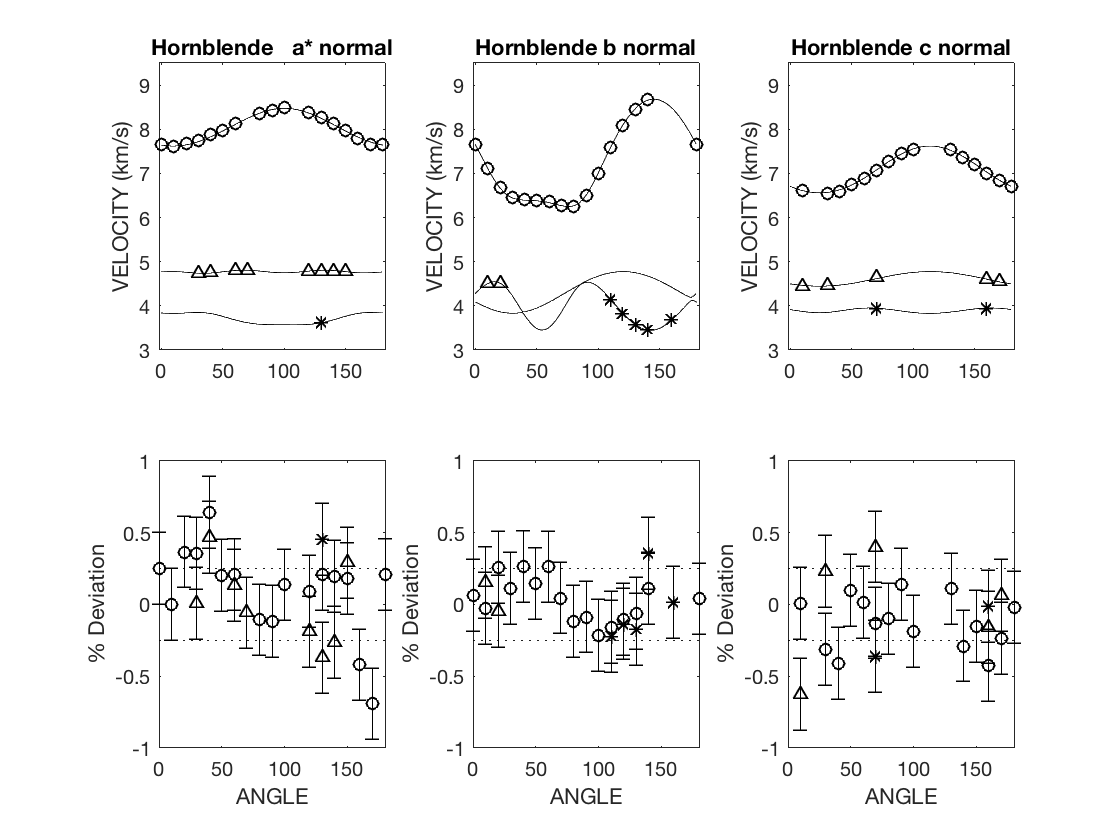


BWPlot(Results,2,1)

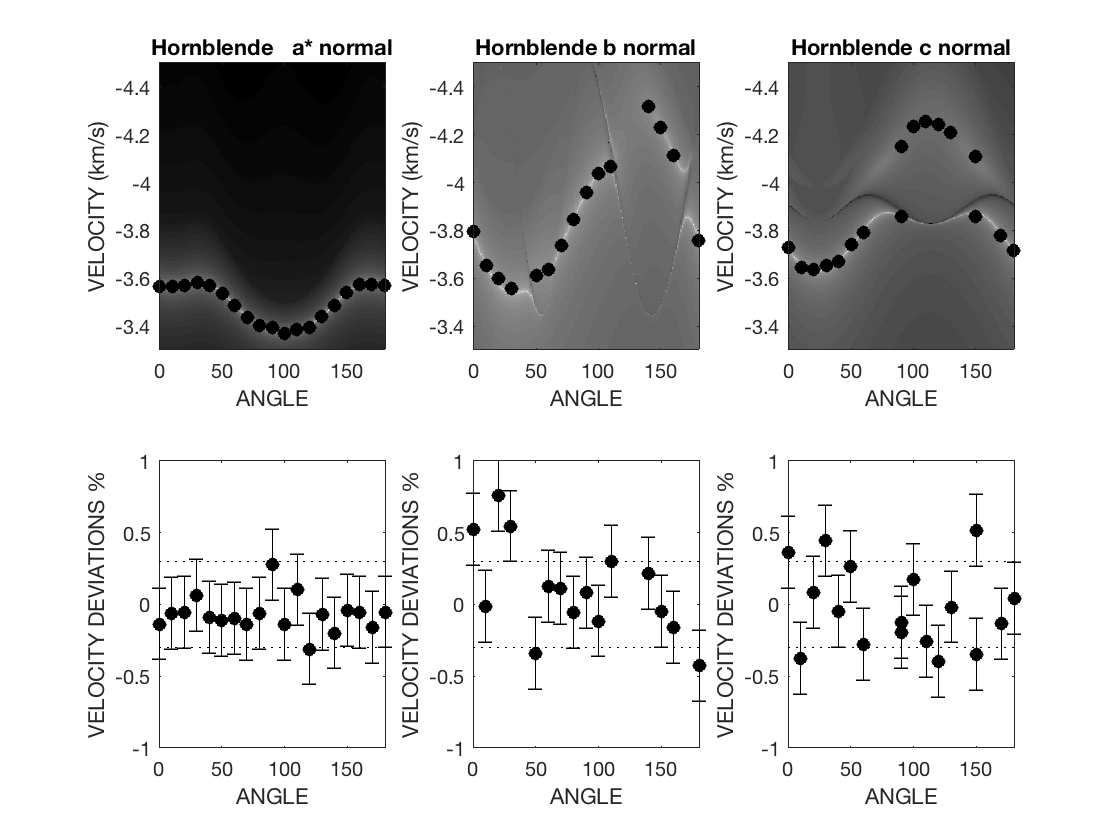

SWPlot(Results,3,1)

The results are summarized in Table 5 of the paper.  Uncertainties based separately on body waves, surface wave and for the joint fit are shown.  The large uncertainties based only on surface waves reflect strong covariance between moduli rather than any intrinsic error. The complementary contributions in the combined data set create a final set of moduli with significantly reduced uncertainty. Here all moduli for this low symmetry crystal have 2*sigma uncertainties less than 1 GPa.